clc, clear all
syms r u b

assume(r,{'real','positive'})
assume(u,{'real','positive'})
assume(b,{'real'})

ri = 4*(0.3960*cos(2.65*(u*b+1.4)));
rj = 4*(-0.99*sin(u*b+1.4));
rk = 0*u;

r = [ri rj rk]

$$r = \left(\begin{array}{ccc} \frac{198\,\cos\left(\frac{53\,b\,u}{20}+\frac{371}{100}\right)}{125} & -\frac{99\,\sin\left(b\,u+\frac{7}{5}\right)}{25} & 0 \end{array}\right)$$

dr=diff(r,u)

$$dr = \left(\begin{array}{ccc} -\frac{5247\,b\,\sin\left(\frac{53\,b\,u}{20}+\frac{371}{100}\right)}{1250} & -\frac{99\,b\,\cos\left(b\,u+\frac{7}{5}\right)}{25} & 0 \end{array}\right)$$

T_hat=dr./norm(dr);
T_hat=simplify(T_hat)

$$T\_hat = \begin{array}{l} \left(\begin{array}{ccc} -\frac{53\,b\,\sin\left(\frac{53\,b\,u}{20}+\frac{371}{100}\right)}{\sigma_{1}} & -\frac{50\,b\,\cos\left(b\,u+\frac{7}{5}\right)}{\sigma_{1}} & 0 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\left|b\right|\,\sqrt{2809\,{\sin\left(\frac{53\,b\,u}{20}+\frac{371}{100}\right)}^{2}+2500\,{\cos\left(b\,u+\frac{7}{5}\right)}^{2}} \end{array}$$

linspeed = simplify(norm(dr))

$$linspeed = \frac{99\,\left|b\right|\,\sqrt{2809\,{\sin\left(\frac{53\,b\,u}{20}+\frac{371}{100}\right)}^{2}+2500\,{\cos\left(b\,u+\frac{7}{5}\right)}^{2}}}{1250}$$

d = 0.235; % wheel base width, meters

ang_vel = simplify(cross(T_hat,diff(T_hat,u)))

$$ang\_vel = \left(\begin{array}{ccc} 0 & 0 & -\frac{265\,b\,\left(73\,\cos\left(\frac{33\,b\,u}{20}+\frac{231}{100}\right)+33\,\cos\left(\frac{73\,b\,u}{20}+\frac{511}{100}\right)\right)}{2\,\left(2500\,\cos\left(2\,b\,u+\frac{14}{5}\right)-2809\,\cos\left(\frac{53\,b\,u}{10}+\frac{371}{50}\right)+5309\right)} \end{array}\right)$$

VL = simplify(linspeed - ang_vel(3)*d/2);
VR = simplify(linspeed + ang_vel(3)*d/2);
VL, VR

$$VL = \frac{99\,\left|b\right|\,\sqrt{2809\,{\sin\left(\frac{53\,b\,u}{20}+\frac{371}{100}\right)}^{2}+2500\,{\cos\left(b\,u+\frac{7}{5}\right)}^{2}}}{1250}+\frac{2491\,b\,\left(73\,\cos\left(\frac{33\,b\,u}{20}+\frac{231}{100}\right)+33\,\cos\left(\frac{73\,b\,u}{20}+\frac{511}{100}\right)\right)}{160\,\left(2500\,\cos\left(2\,b\,u+\frac{14}{5}\right)-2809\,\cos\left(\frac{53\,b\,u}{10}+\frac{371}{50}\right)+5309\right)}$$

$$VR = \frac{99\,\left|b\right|\,\sqrt{2809\,{\sin\left(\frac{53\,b\,u}{20}+\frac{371}{100}\right)}^{2}+2500\,{\cos\left(b\,u+\frac{7}{5}\right)}^{2}}}{1250}-\frac{2491\,b\,\left(73\,\cos\left(\frac{33\,b\,u}{20}+\frac{231}{100}\right)+33\,\cos\left(\frac{73\,b\,u}{20}+\frac{511}{100}\right)\right)}{160\,\left(2500\,\cos\left(2\,b\,u+\frac{14}{5}\right)-2809\,\cos\left(\frac{53\,b\,u}{10}+\frac{371}{50}\right)+5309\right)}$$

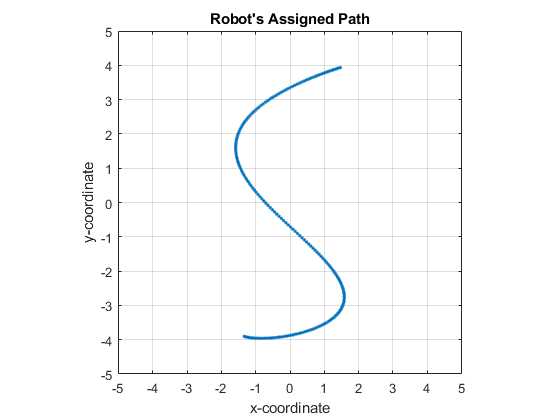

b_num = 1/10;
clear u_num r_num VL_num VR_num
u_num = linspace(0,3.2/b_num,200);
    
for n=1:length(u_num)
    r_num(n,:)=double(subs(r,[u,b],[u_num(n),b_num]));
    VL_num(n,:)=double(subs(VL,[u,b],[u_num(n),b_num]));
    VR_num(n,:)=double(subs(VR,[u,b],[u_num(n),b_num]));
end

save("vlvr.mat","u_num","VL_num","VR_num")

figure
plot(r_num(:,1),r_num(:,2),'.-')
axis equal
axis([-5 5 -5 5]);
xticks([-5 -4 -3 -2 -1 0 1 2 3 4 5])
title('Robot''s Assigned Path')
xlabel('x-coordinate')
ylabel('y-coordinate')
grid on

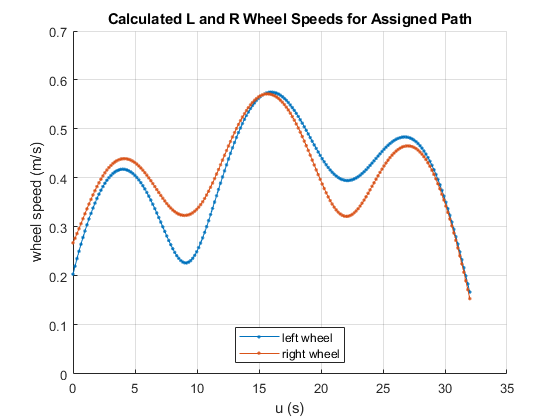


figure
hold on
plot(u_num,VL_num,'.-')
plot(u_num,VR_num, '.-')
title('Calculated L and R Wheel Speeds for Assigned Path')
legend({'left wheel','right wheel'},'Location','south')
xlabel('u (s)')
ylabel('wheel speed (m/s)')
ylim([0,7*b_num]);
grid on

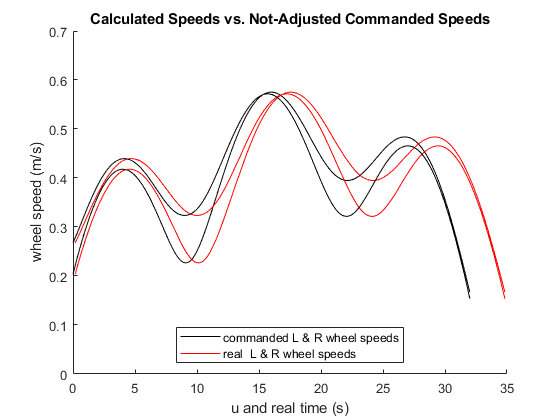


load encoderdata_test.mat % contains 'dataset'
load commandsdata_delay.mat % contains 'commandsdata_delay'

timestamp = dataset(:,1);
posL = dataset(:,2);
posR = dataset(:,3);
AccelX = dataset(:,4);
AccelY = dataset(:,5);
AccelZ = dataset(:,6);

dposL = diff(posL)./diff(timestamp);
dposR = diff(posR)./diff(timestamp);

figure
hold on

st = 1;
en = length(dposL);

plot(u_num,VL_num,'k-')
plot(commandsdata_delay(:,1),commandsdata_delay(:,2:3),'r-')
plot(u_num,VR_num, 'k-')
title('Calculated Speeds vs. Not-Adjusted Commanded Speeds')
legend({'commanded L & R wheel speeds', 'real  L & R wheel speeds'},'Location','south')
xlabel('u and real time (s)')
ylabel('wheel speed (m/s)')
ylim([0,7*b_num]);

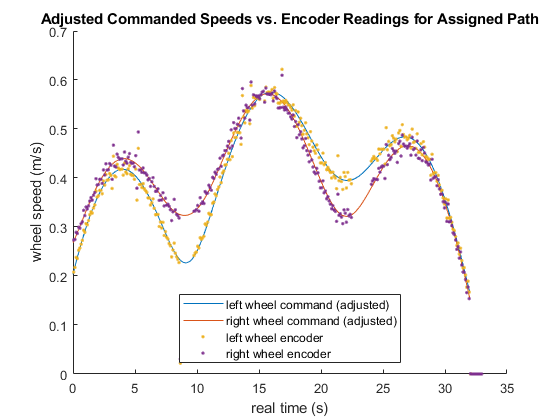


figure
hold on

st = 1;
en = length(dposL);

plot(u_num,VL_num,'-')
plot(u_num,VR_num, '-')
plot(timestamp(st:en),dposL(st:en), '.')
plot(timestamp(st:en),dposR(st:en), '.')
title('Adjusted Commanded Speeds vs. Encoder Readings for Assigned Path')
legend({'left wheel command (adjusted)','right wheel command (adjusted)','left wheel encoder', 'right wheel encoder'},'Location','south')
xlabel('real time (s)')
ylabel('wheel speed (m/s)')
ylim([0,7*b_num]);

hold off